# MLP Model of SI Engine Torque Dynamics

This example describes modeling the nonlinear torque dynamics of a spark-ignition (SI) engine as a Multi-Layer Perceptron model. The identified model can be used for hardware-in-the-loop (HIL) testing, powertrain control, diagnostic, and training algorithm design. For example, you can use the model for aftertreatment control and diagnostics algorithm development. For more information on nonlinear MLP model, see [MLP](https://www.mathworks.com/help/releases/R2024b/ident/ref/idneuralstatespace.createmlpnetwork.html?searchHighlight=MLP&s_tid=doc_srchtitle)

You use measurements of the system inputs and outputs to identify the model. This data can come from measurements on a real engine or a high-fidelity model such as one created using the Powertrain Blockset™ SI Reference application. 

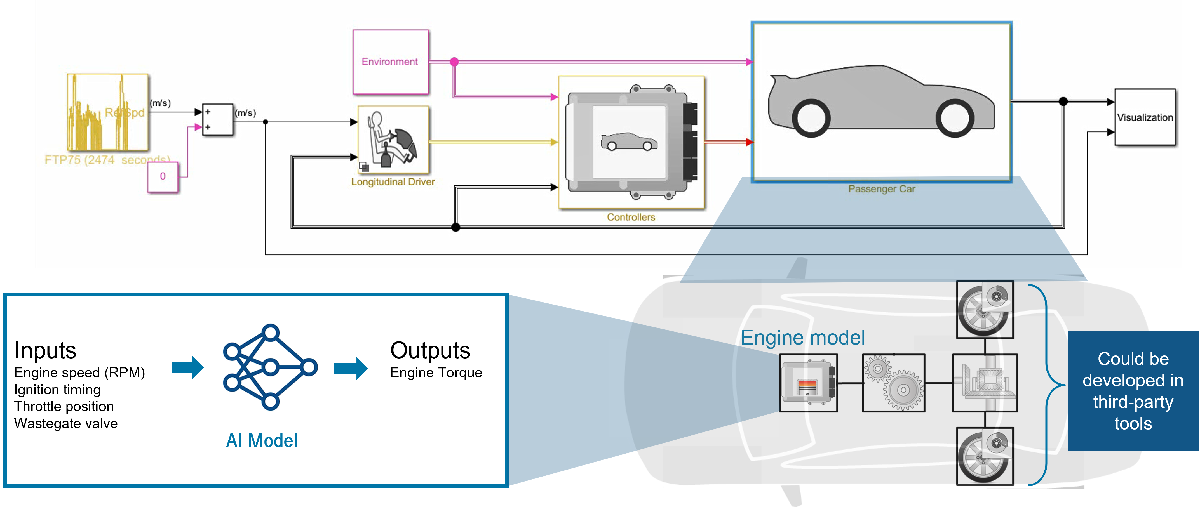

## Data Preparation

Load and display the engine data timetable.

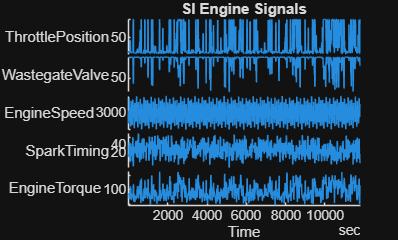

load SIEngineData IOData
stackedplot(IOData)
title('SI Engine Signals')

  The timetable contains over one hundred thousands observations of five variables measured at 10 Hz.

- Throttle position (degrees)

- Wastegate valve area (aperture percentage) 

- Engine speed (RPM)

- Spark timing (degrees)

- Engine torque (N m)

Split the data into estimation (first 60000 data points) and validation (remaining data points) portions.

eData = IOData(1:6e4,:);     % portion used for estimation
%change it to 8e4
vData = IOData(6e4+1:end,:); % portion used for validation

Add inputs and outputs

Inputs = ["ThrottlePosition","WastegateValve","EngineSpeed","SparkTiming"];
Output = "EngineTorque";

Start Reduced Order Modeling App and Select from Imported data and Choose IOData as input. Setup Engine Torque as output

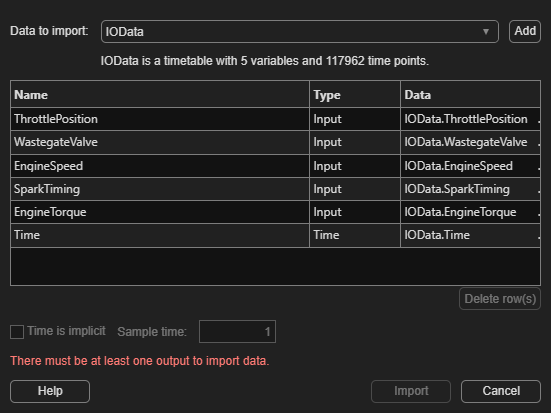

useROMApp=true;
if(useROMApp)
reducedOrderModeler;% Add screen shot of import Data
 

Please select MATLAB Variable

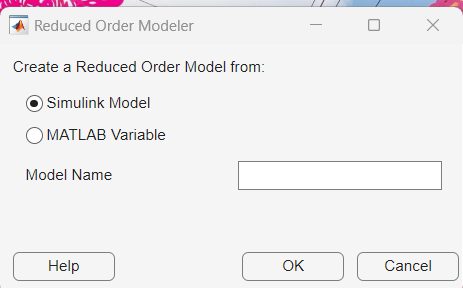

Once selected please select MATLAB variable we want to import in our case it is IOData

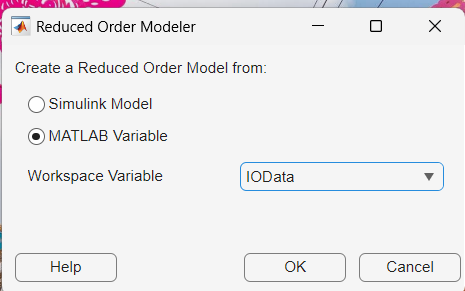

Once Data is selected please select required inputs and outputs, Engine Torque is what we want  to predict using ROM

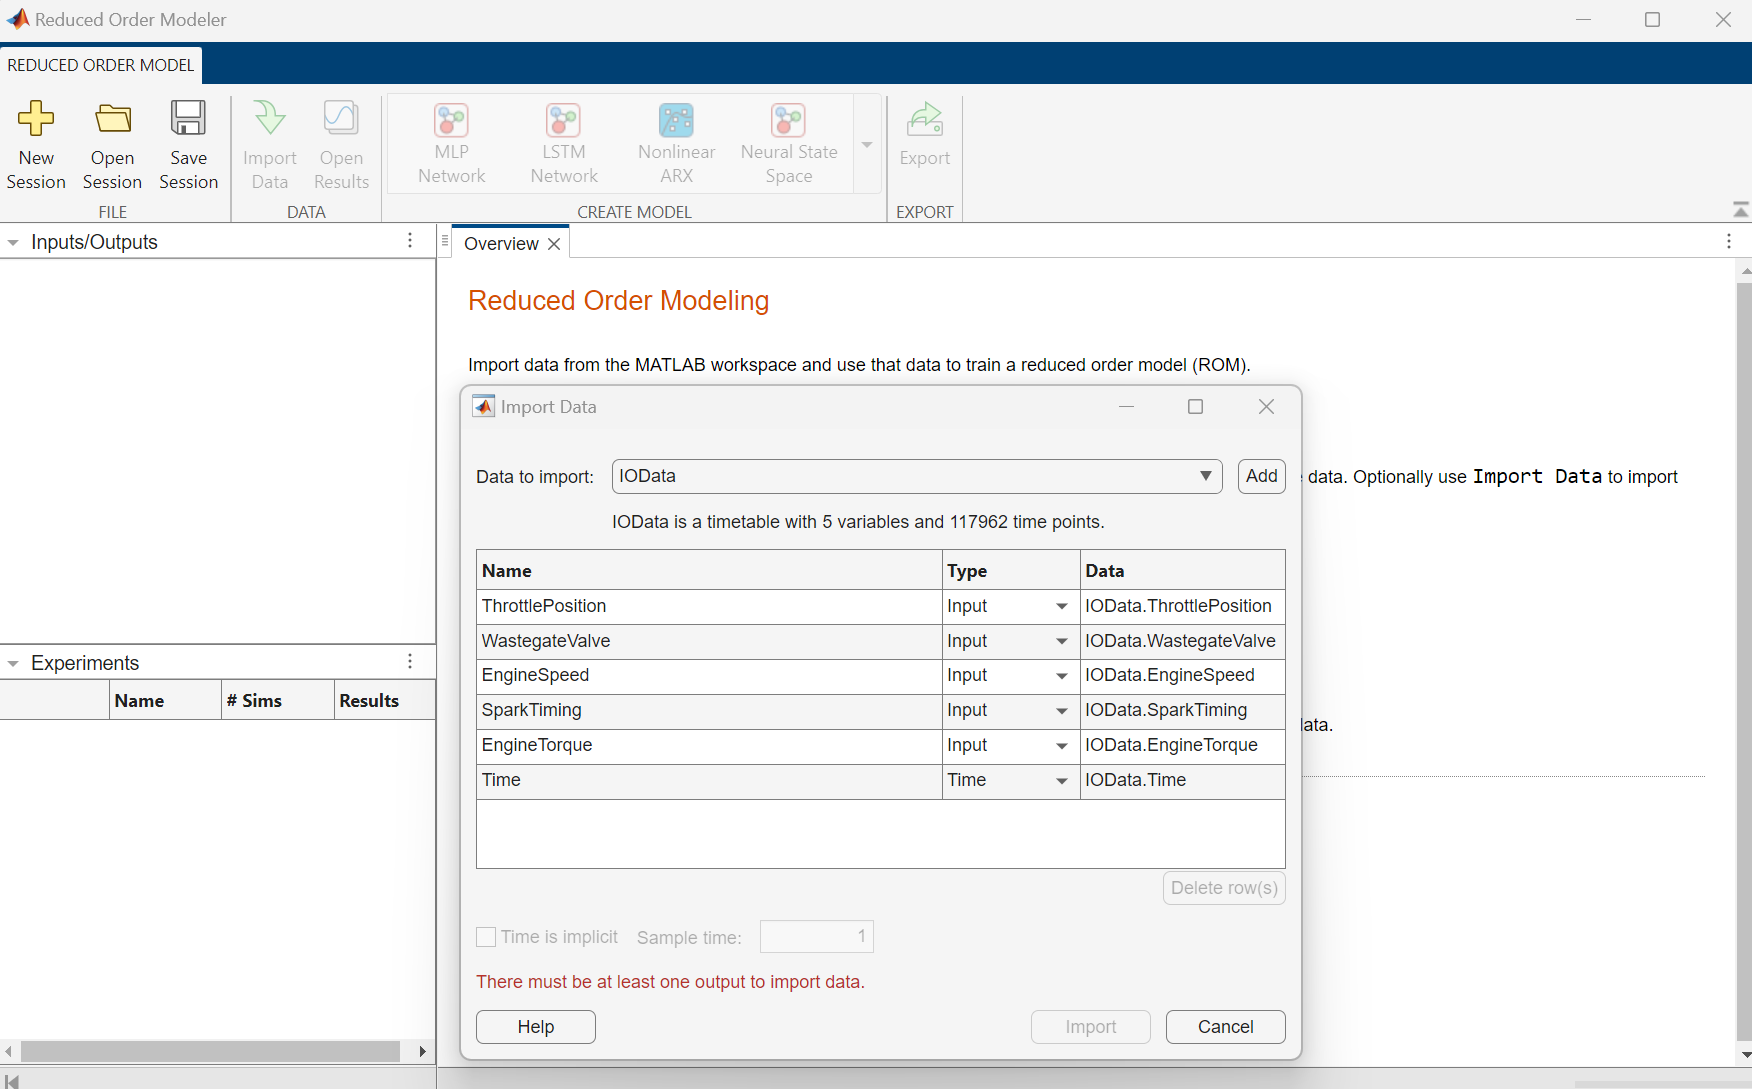

Examine the Randomness of Inputs and Outputs if we see strong correlation please select one of the correlated inputs and do the same for outputs.

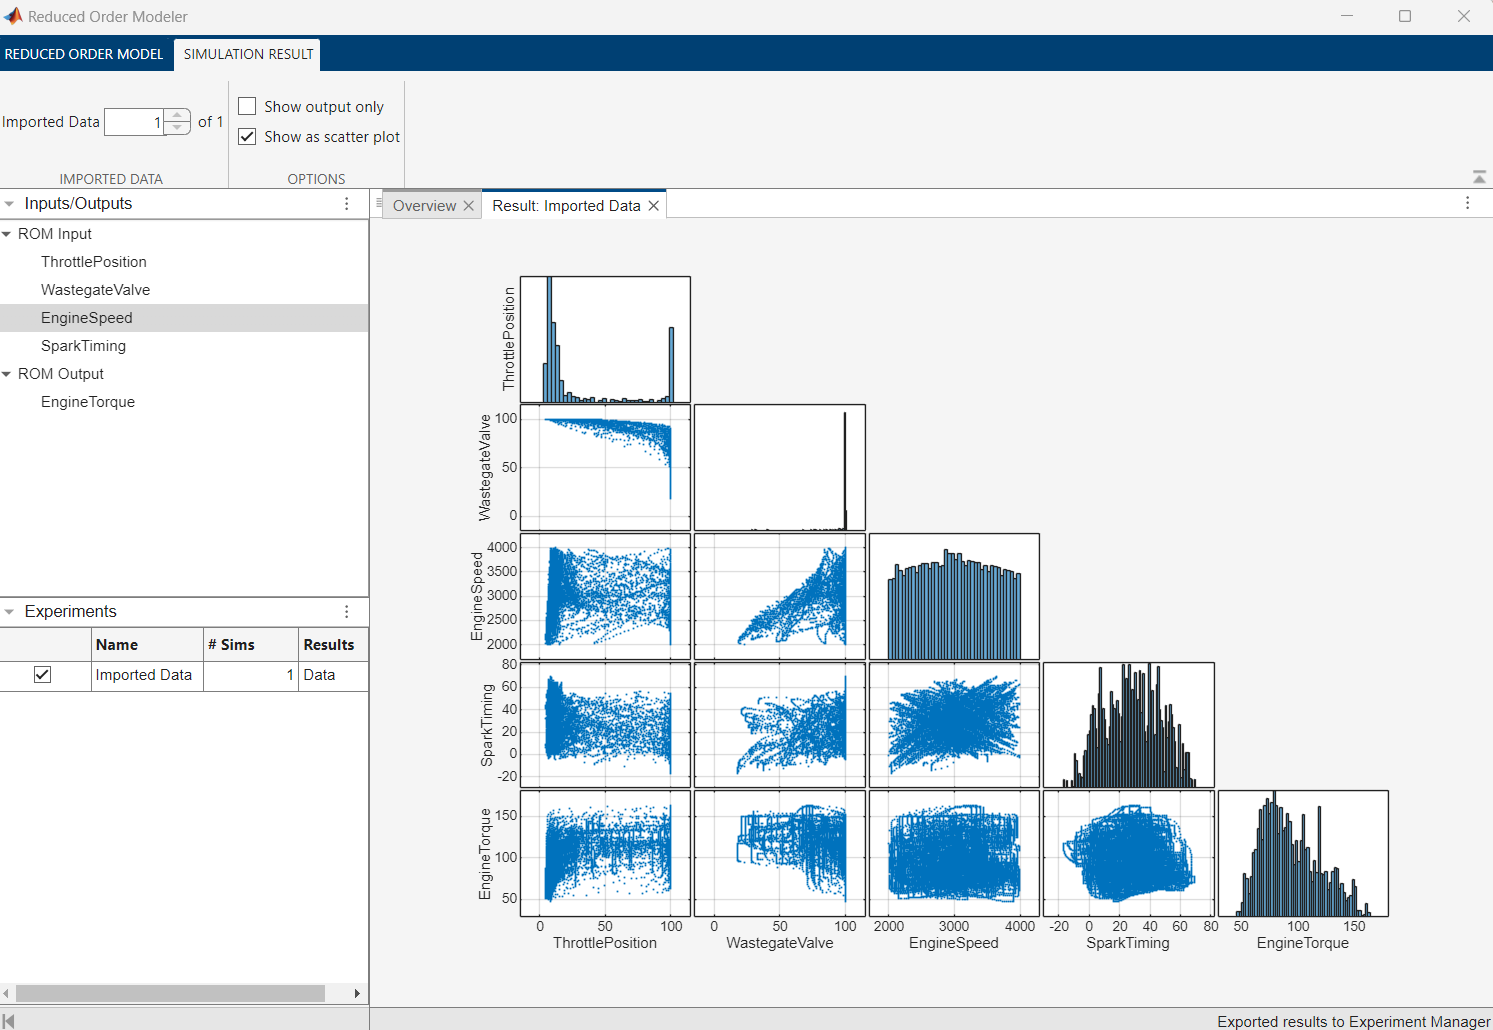

Now set up an experiment that uses MLP with following parameters

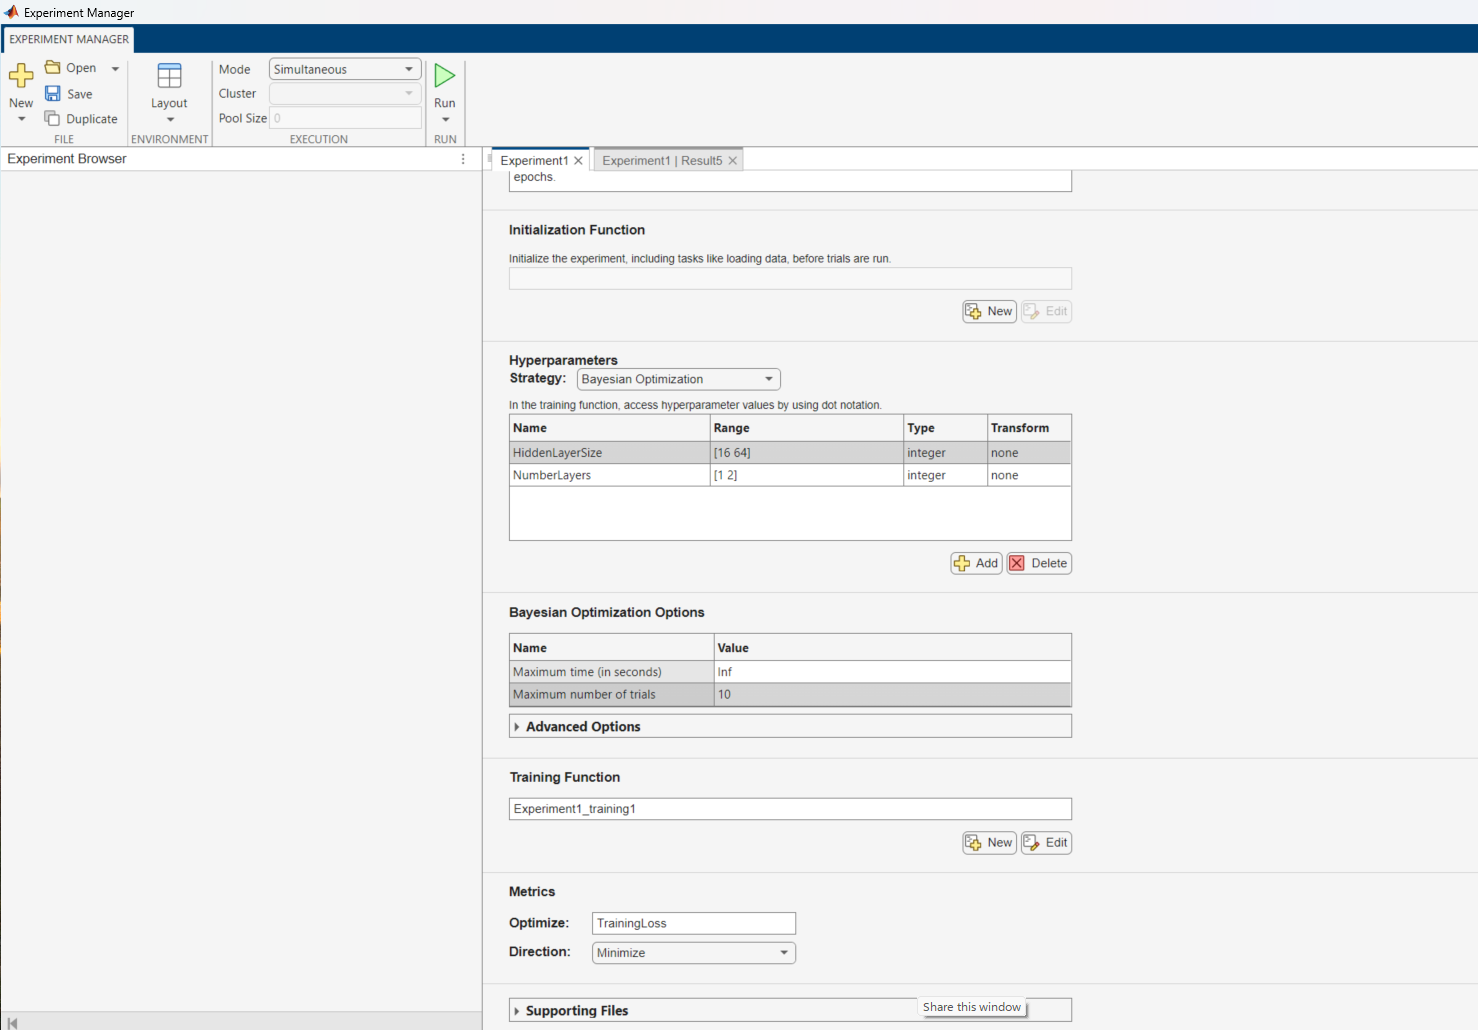

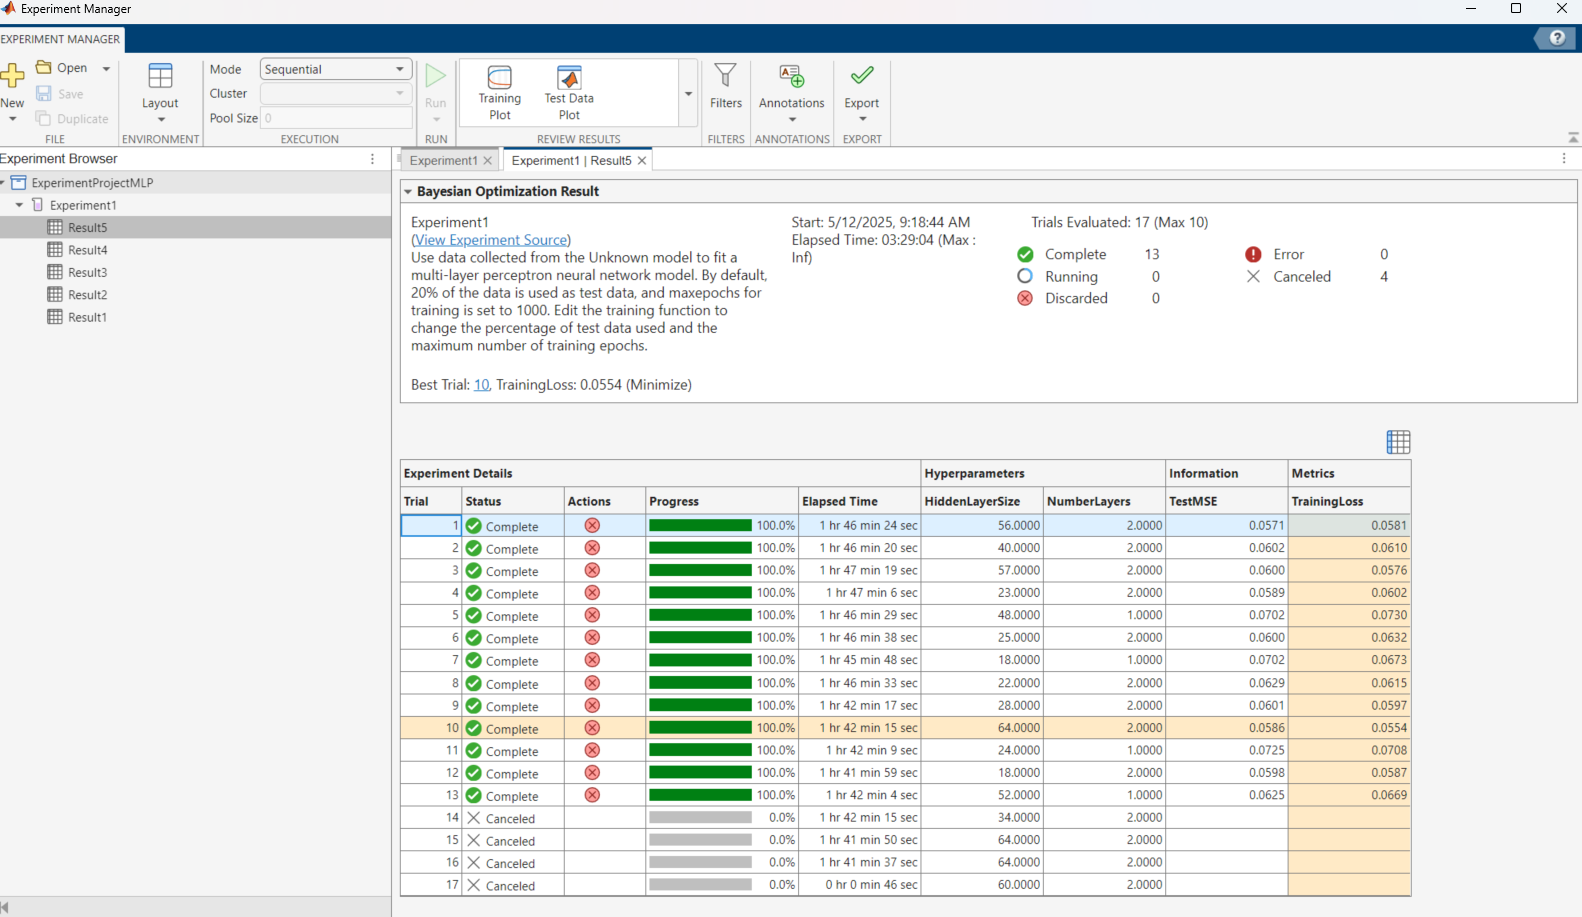

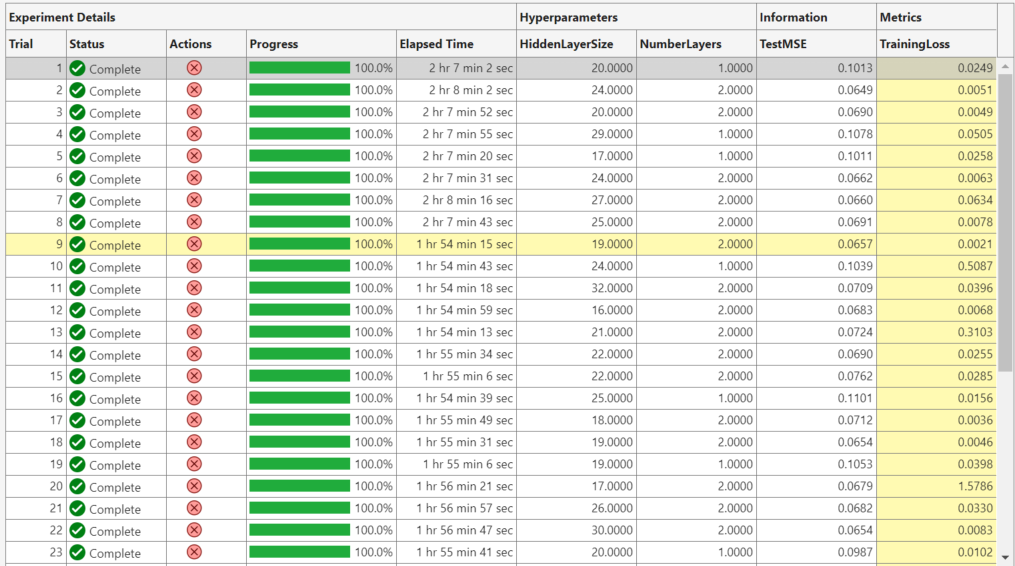

Pick the Best Model and export trainingOutput.

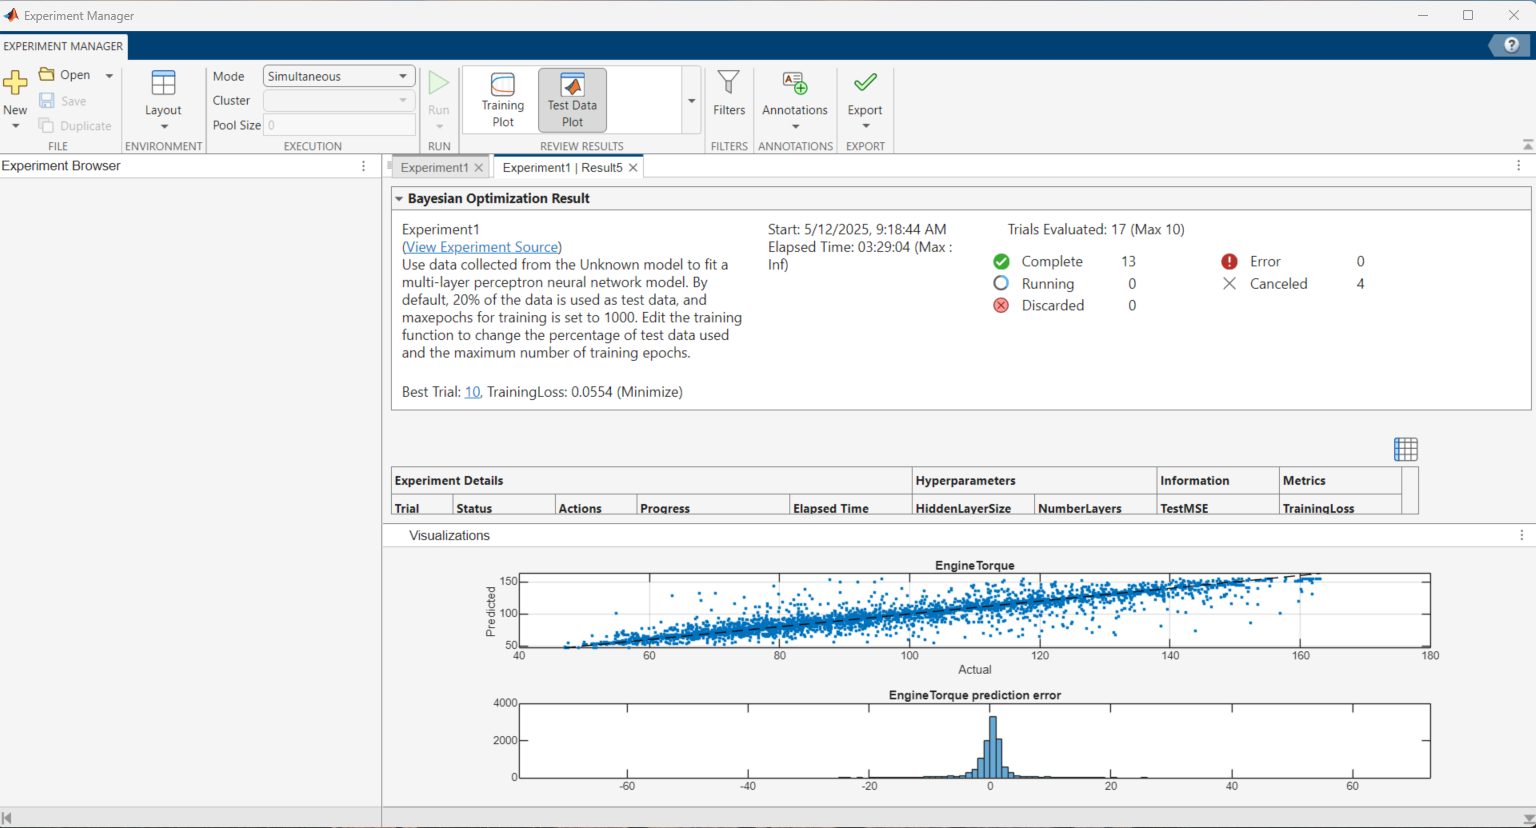 

Extract MLP and Noramlization object that contains both input and output 

else

Unable to resolve the name 'trainingOutputMLP.Network'.

    load trainingOutputMLP.mat;
end

mlp_rom=trainingOutputMLP.Network;
%Analyzenet so we can see number of learnables
analyzeNetwork(mlp_rom);

Create a Table of Normalization Values

NormalizationValues=trainingOutputMLP.Normalization;

p=NormalizationValues.Sigma;
p1=NormalizationValues.Mu;
temp=table(p',p1');
NormTable=temp;
NormTable.Properties.RowNames=[Inputs,Output];
NormTable.Properties.VariableNames=["Sigma","Mu"];

%Retain all design data
MLPDataDic=setupDataDictionary("SIEngineDataModel",NormTable);

Now Start integrating Model in Simulink, Point to the network and add Normalization and Denormalization blocks using the Network from above and Data from above.

load_system('MLP_ROM2024a.slx');
open_system('MLP_ROM2024a.slx')

- Open  MLP_ROM.slx in the Model folder

- Link Playback to IOData and View Data through Block parameter

- Open MLP Model Subsystem, and ROM then attach predict model to MLPNetwork.mat and examine the Normalizer and Denormalize blocks

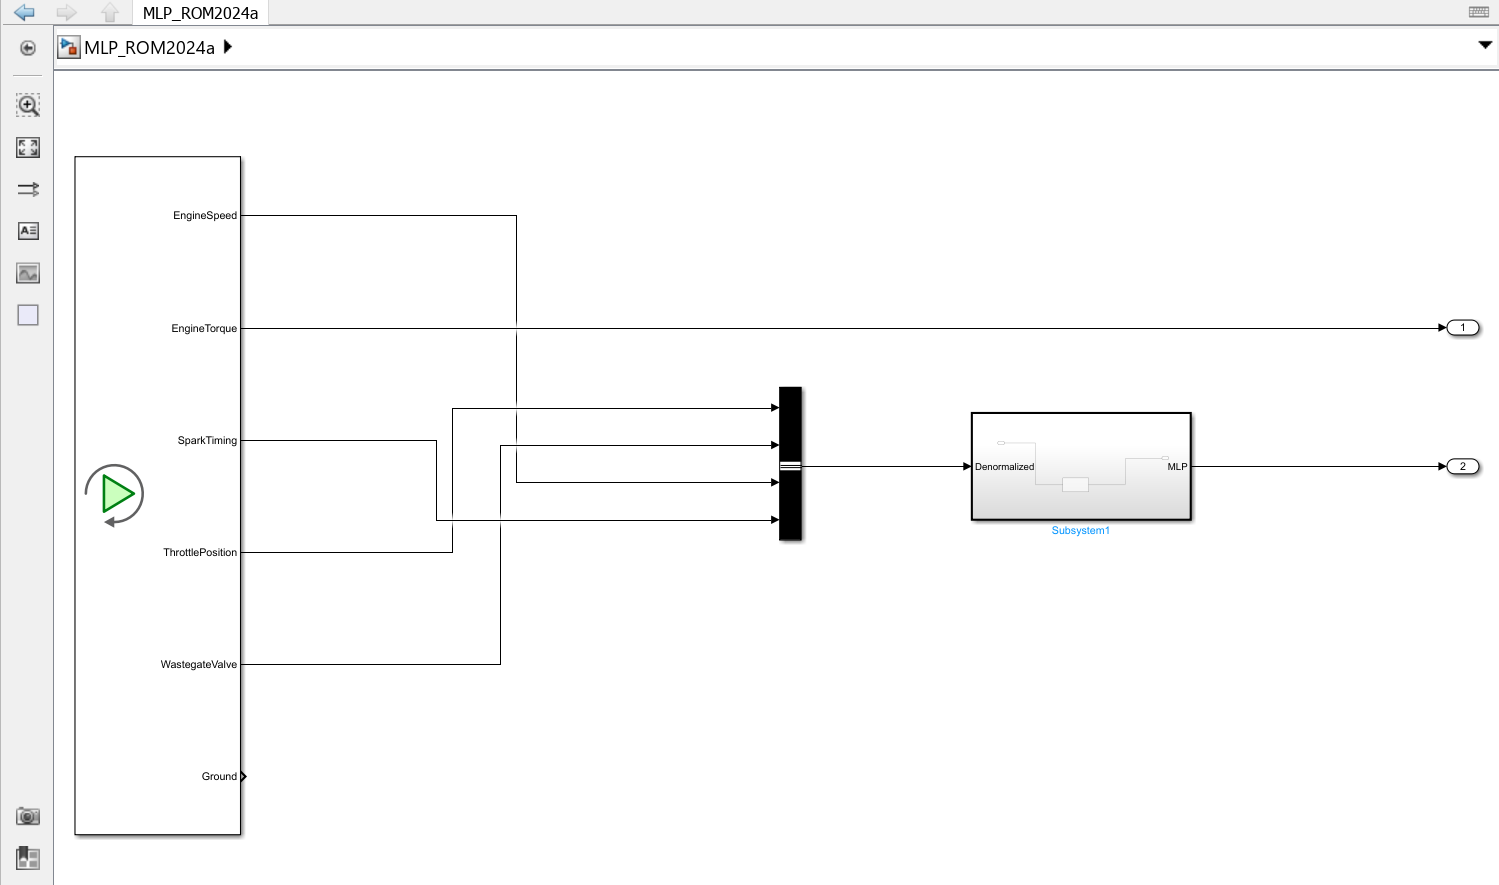

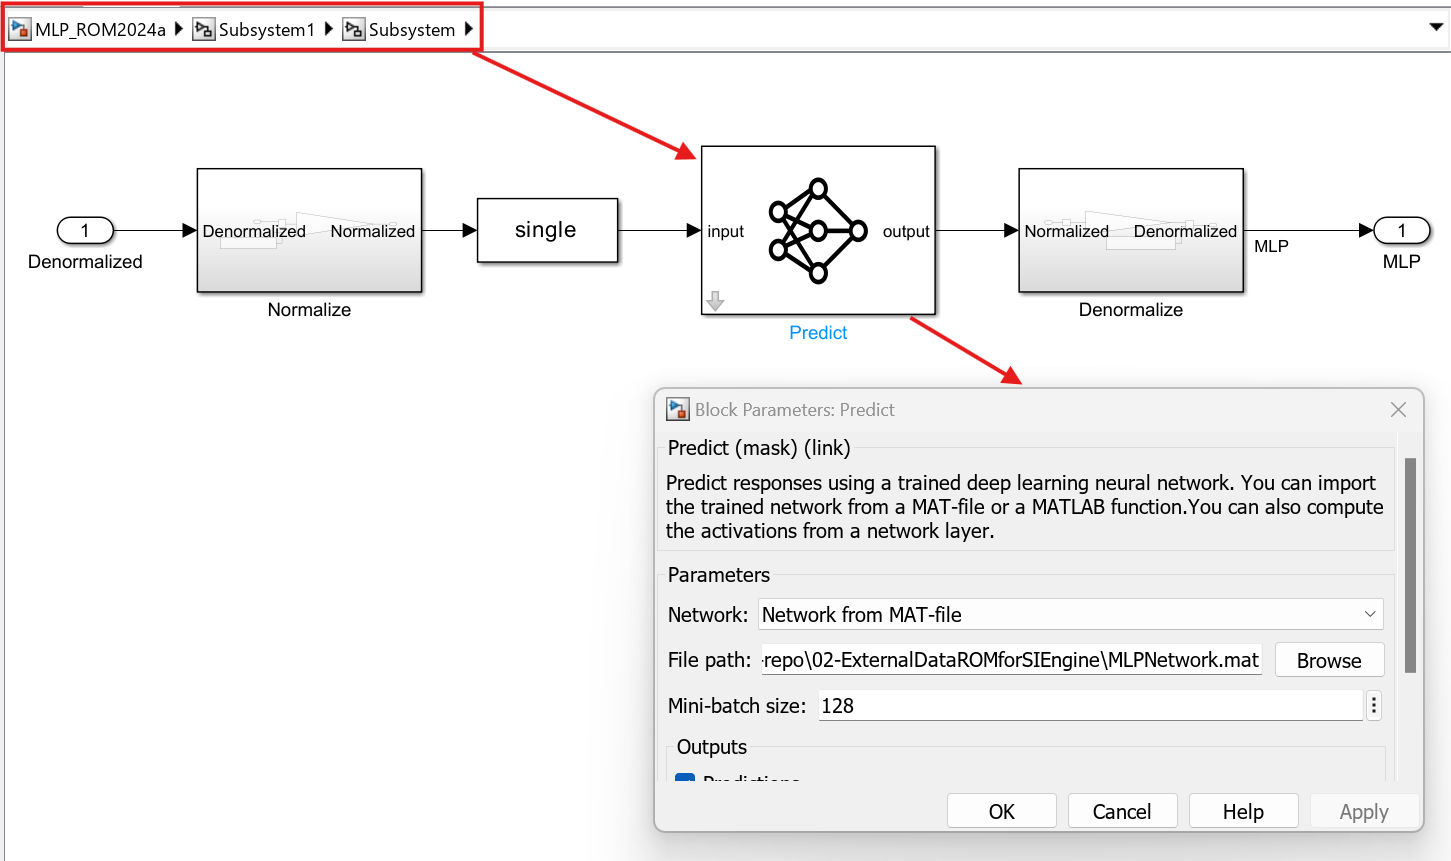

4. Run the Model and verify the data in Data Inspector,

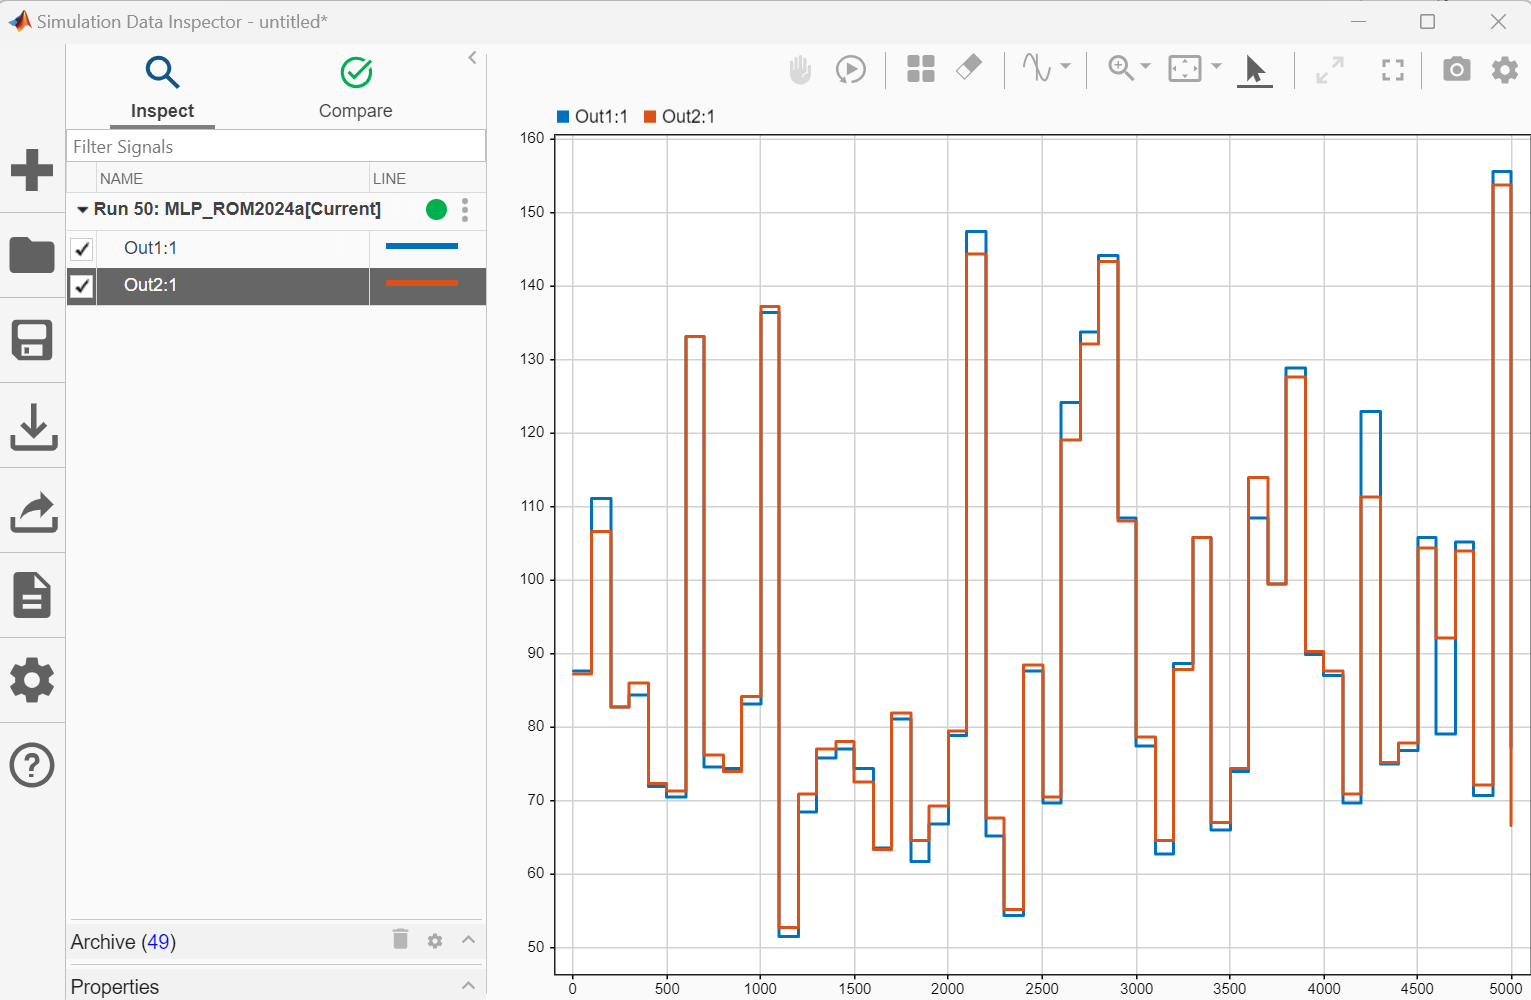 

5. Go to Apps and open SIL/PIL manager and select the Model Blocks in SIL/PIL Mode and Verify

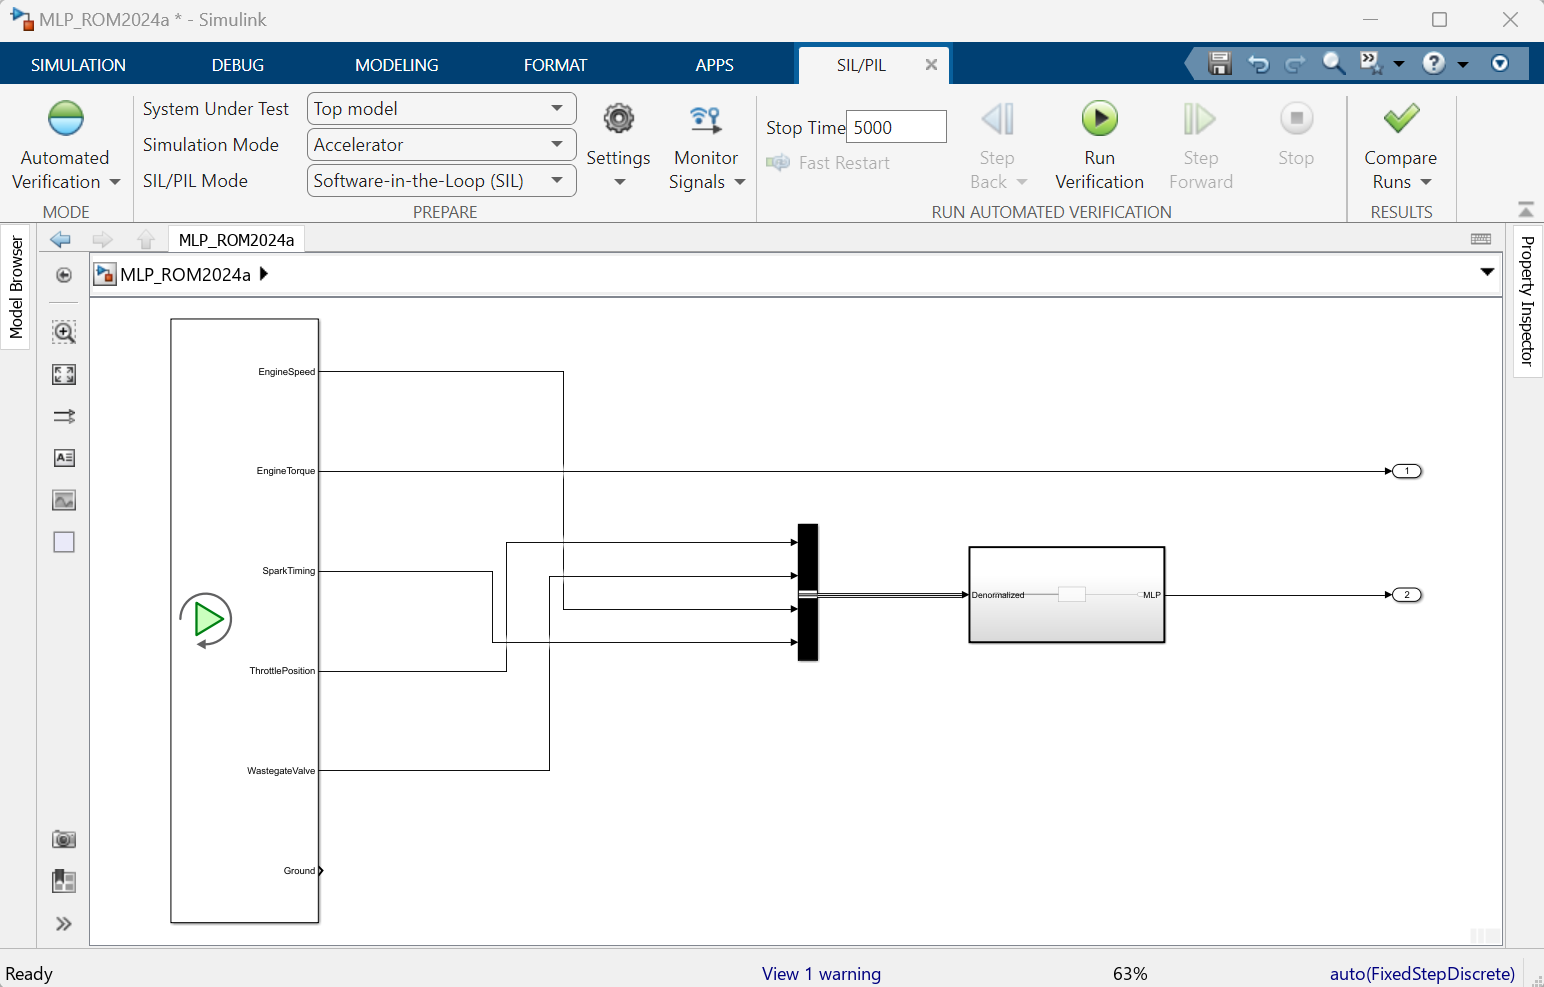

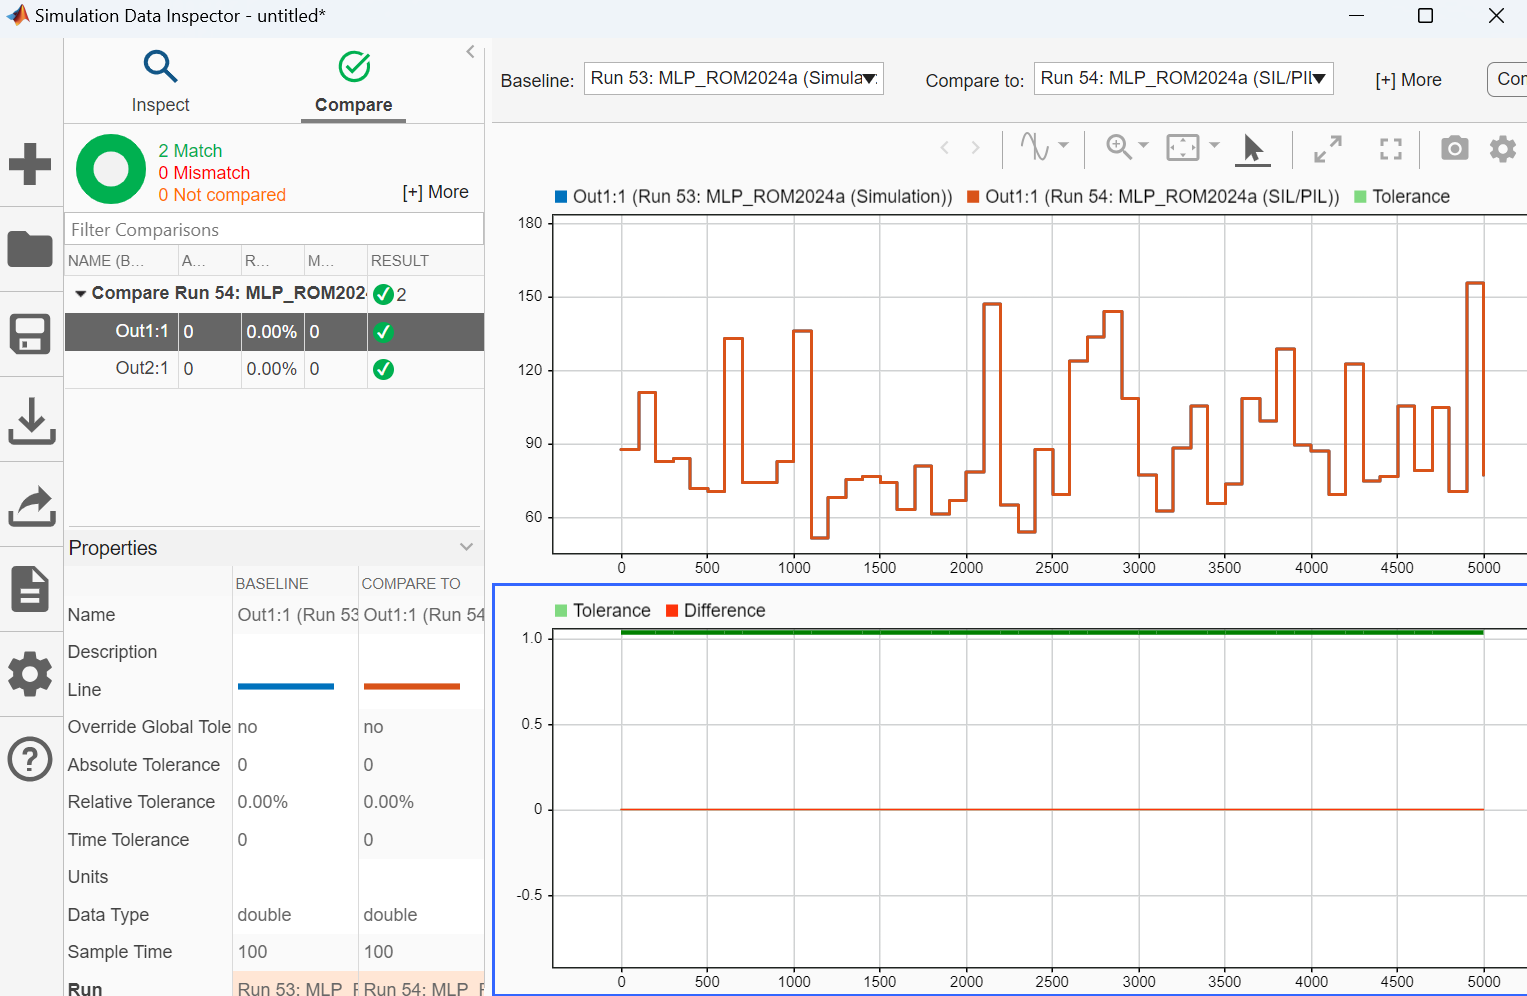

function [DataDictObj] = setupDataDictionary(proj,ModelParams)
%%SETUPDATADICTIONARY - Helper function to load external data (from Excel
%%in this case) into a Simulink Data Dictionary.

% Make sure we are starting fresh
Simulink.data.dictionary.closeAll('-discard');

% Define the name of the DD file
SLDDFilename = fullfile("MLP_ROM.sldd");

if isfile(SLDDFilename)
    delete(SLDDFilename);
end %if

% Read data from Excel

% Create a new data dictionary
DataDictObj = Simulink.data.dictionary.create(SLDDFilename);

% Access the 'Design Data' section of the SLDD
dDataSectObj  = getSection(DataDictObj, "Design Data");

% Loop through the MATLAB Table we read in from Excel and add the to the
% "Design Data" section of the data dictionary.
for ii = 1:height(ModelParams)
    addEntry(dDataSectObj, ModelParams.Properties.RowNames(ii)+"Sigma", ModelParams.Sigma(ii));
    addEntry(dDataSectObj, ModelParams.Properties.RowNames(ii)+"Mu",ModelParams.Mu(ii));
end % for

% We populated the SLDD with MATLAB Variables but could just as easily
% used Simulink Parameters.  This work does not look toward code gen.

% % (Optional) Add Simulink Parameters to the SLDD
% % myParam = Simulink.Parameter;
% % myParam.Value = 42;
% % myParam.CoderInfo.StorageClass = 'ExportedGlobal';


% Save the changes to the data dictionary
saveChanges(DataDictObj);

end %setupDataDictionary

Clean up environment for next exercise


clear
rmpath(genpath('C:\ROM_Workshop\02-ExternalDataROMforSIEngine'));

*Copyright 2025, The MathWorks, Inc.*